# 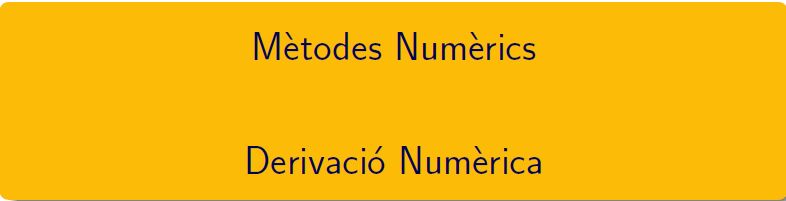

===============================================================================

# Pràctica 8. Derivación Numérica

## Introducción 

A més a més dels exercicis d'aquest script teniu disponibles exercicis en el document Guia-Lab8.pdf i en el document CN_full7.pdf, els podeu trobar en el campus virtual. 

### Derivación numérica con Matlab®

Use the `diff` function to approximate partial derivatives with the syntax `Y = diff(f)/h`, where `f` is a vector of function values evaluated over some domain, `X`, and `h` is an appropriate step size.

For example, the first derivative of `sin(x)` with respect to `x` is `cos(x)`, and the second derivative with respect to `x` is `-sin(x)`. You can use `diff` to approximate these derivatives.

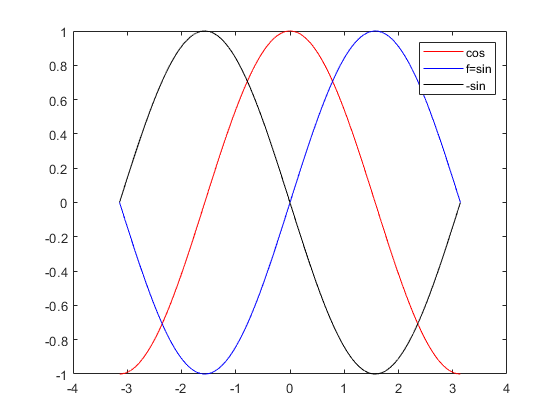

h = 0.001;       % step size
X = -pi:h:pi;    % domain
f = sin(X);      % range
Y = diff(f)/h;   % first derivative
Z = diff(Y)/h;   % second derivative
plot(X(:,1:length(Y)),Y,'r',X,f,'b', X(:,1:length(Z)),Z,'k'),legend('cos','f=sin','-sin')

In this plot the blue line corresponds to the original function, `sin`. The red line corresponds to the calculated first derivative, `cos`, and the black line corresponds to the calculated second derivative, `-sin`.

*Copyright 2015 The MathWorks, Inc.*

## Fórmulas básicas.

### Ejercicio 1. 

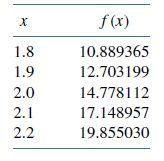

Calcular f'(2.0) con h=0.1 y h=02. Los datos son de f(x)=x*e^x, calcular los errores absolutos. Crear tabla para visualitzar error absoluto en las fórmulas usadas

x = [1.8:0.1:2.2]; y = [x.*exp(x)]; disp([x;y]');

    1.8000   10.8894
    1.9000   12.7032
    2.0000   14.7781
    2.1000   17.1490
    2.2000   19.8550



valor = exp(x(3))+x(3)*exp(x(3));
% h = 0.2
yp1 = (y(5)-y(1))/(2*0.2); % f(x+h)-f(x-h)/2h
R = [valor,yp1,abs(yp1-valor),abs(yp1-valor)/valor];
% h = 0.1
yp2 = (y(4)-y(2))/(2*0.1); % f(x+h)-f(x-h)/2h
R = [R;valor,yp2,abs(yp2-valor),abs(yp2-valor)/valor];
format short g;
rowNames = {'h = 0.2','h = 0.1'};
varNames = {'y´(2.0)','valor aproximat','error absolut','error relatiu'};
T = array2table(R,'RowNames',rowNames,'VariableNames',varNames); disp(T)

               y´(2.0)    valor aproximat    error absolut    error relatiu
               _______    _______________    _____________    _____________

    h = 0.2    22.167         22.414            0.24699          0.011142  
    h = 0.1    22.167         22.229           0.061619         0.0027797  



### Ejercicio 2 

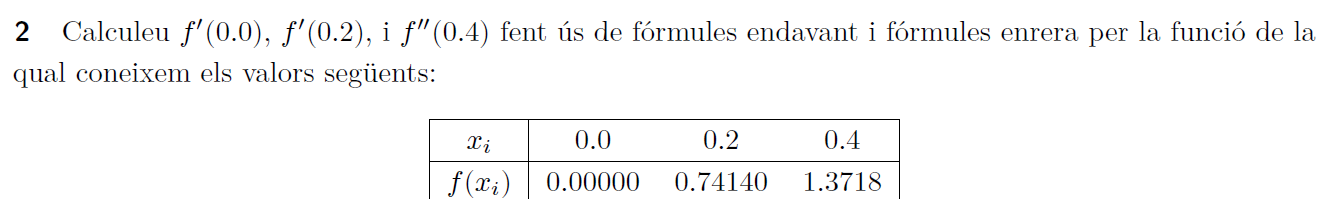

clearvars;
x = [0 0.2 0.4]; y = [0 0.74140 1.3718];
yp(1) = (y(2)-y(1))/0.2;    % f'(0) endavant
yp(2) = (y(3)-y(2))/0.2;    % f'(0.2) endavant
yp(3) = NaN;                % f'(0.4) endavant
format short g;
varNames = {'method','y´(0)','y´(0.2)','y´(0.4)'};
T = table(categorical({'forward'}),yp(1),yp(2),yp(3),'VariableNames',varNames); disp(T)

    method     y´(0)    y´(0.2)    y´(0.4)
    _______    _____    _______    _______

    forward    3.707     3.152       NaN  



clearvars;
x = [0 0.2 0.4]; y = [0 0.74140 1.3718];
yp(1) = NaN;                % f'(0) enrera
yp(2) = (y(2)-y(1))/0.2;    % f'(0.2) enrera
yp(3) = (y(3)-y(2))/0.2;    % f'(0.4) enrera
format short g;
varNames = {'method','y´(0)','y´(0.2)','y´(0.4)'};
T = table(categorical({'backward'}),yp(1),yp(2),yp(3),'VariableNames',varNames); disp(T)

     method     y´(0)    y´(0.2)    y´(0.4)
    ________    _____    _______    _______

    backward     NaN      3.707      3.152 



### Ejercicio 3

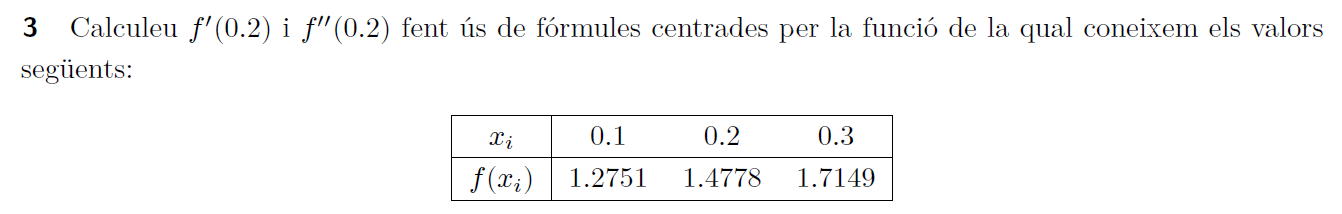

clearvars;
x = [0.1, 0.2,0.3]; y = [1.2751 1.4778 1.7149];
h =  x(2)-x(1);
yp = (y(3)-y(1))/(2*h);
ypp = (y(3)-2*y(2)+y(1))/(h^2);
rowNames = {'y´(2)','y´´(2)'};
varNames = {'valor aproximat'};
R = [yp;ypp];
T = array2table(R,"RowNames",rowNames,"VariableNames",varNames)

T = 2×1 table
              valor aproximat
              _______________

    y´(2)          2.199     
    y´´(2)          3.44     


### **Ejercicio 4**

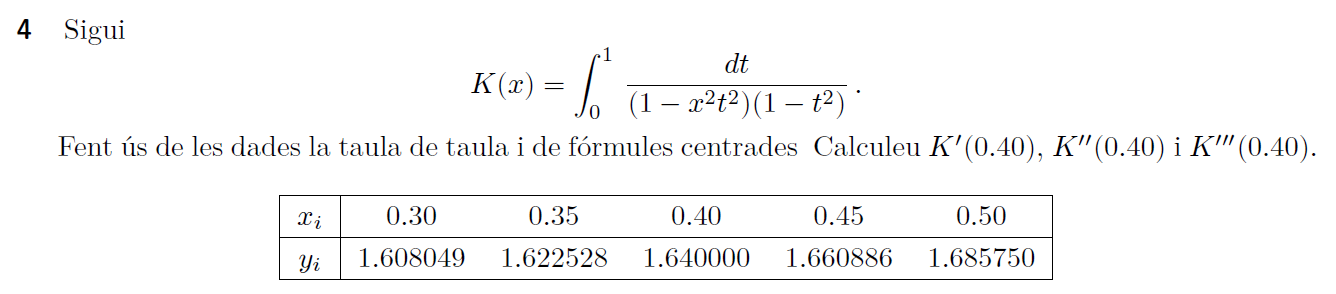

x = [0.3:0.05:0.5];
x2 = x.^2;
format
y = round(ellipke(x2),7,'significant');
T = array2table([x;y]',"VariableNames",{'x_i','y_i'}); disp(T)

    x_i      y_i  
    ____    ______

     0.3     1.608
    0.35    1.6225
     0.4      1.64
    0.45    1.6609
     0.5    1.6858



h = x(2)-x(1);   % separació equidistant
yp = (y(4)-y(2))/(2*h);                     % K'(0.40) centrada derivada primera
ypp = (y(4)-2*y(3)+y(2))/(h^2);             % K''(0.40) centrada derivada segona
yppp = (y(5)-2*y(4)+2*y(2)-y(1))/(8*h^3);   % K'''(0.40) centrada derivada tercera
rowNames = {'K´(0.4)','K´´(0.4)','K´´´(0.4)'};
varNames = {'valor aproximat'};
R = [yp;ypp;yppp];
T = array2table(R,"RowNames",rowNames,"VariableNames",varNames)

T = 3×1 table
                 valor aproximat
                 _______________

    K´(0.4)          0.38358    
    K´´(0.4)          1.3656    
    K´´´(0.4)          0.985    


## Pràctica 16: Comportament de l'error

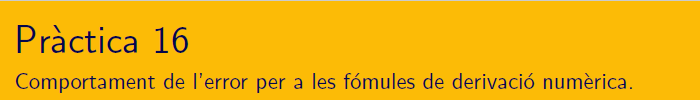

### **Ejercicio 5**

Se sabe que la derivada de $\ln(x)$ en $x=2$ tiene el valor de $f^{\prime}(2)=\frac 12$. Se pide:

a) Aproximar $f^{\prime}(2)$ mediante la fórmula $	\mathbf{F1}\::f^{\prime}(x_0)\approx\frac{f(x_0+h)-f(x_0)}{h}
$, per $h_k=2^{-k}$ para $k=1,2,3\dots, 15.$

format shortG
% Fórmula endavant
f = @(x)log(x);
k = 0:14;
h = 1./2.^k;        % Veure canvis al canviar el 2
fp = (f(2+h)-f(2))./h;

b) Calculad el error absoluto para cada una de las aproximaciones obtenidas. Presentar los resultados en una tabla T2.

Representad el error en una gráfica, absicisas $k=1,2,3\dots, 15$ y ordenadas $log_{10}(error)$

er = abs(fp-0.5);
taula = [h; fp; er]'

taula =             1      0.40547     0.094535
          0.5      0.44629     0.053713
         0.25      0.47113     0.028868
        0.125        0.485     0.015003
       0.0625      0.49235    0.0076535
      0.03125      0.49613     0.003866
     0.015625      0.49806     0.001943
    0.0078125      0.49903   0.00097403
    0.0039063      0.49951   0.00048765
    0.0019531      0.49976   0.00024398


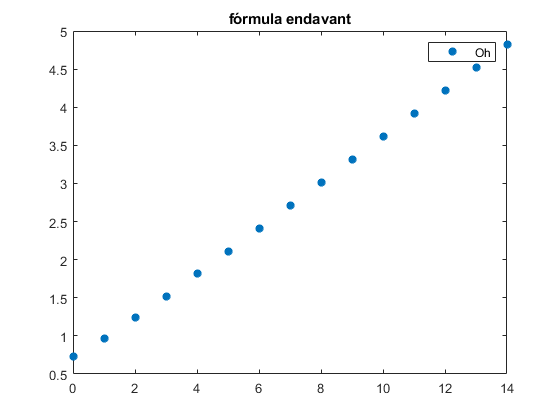

plot(k,-log10(2*er),'*','LineWidth',2),legend('Oh'),title('fórmula endavant')

**c) **Observad la existencia de un h óptimo, a partir del cúal si se toman valores de $h$ más pequeños, los errores crecen. 

Cúal es el valor de h para la fórmula $\mathbf{F1}$?

### **Ejercicio 6  **

Repetir el ejercicio 5 usando la fórmula $\mathbf{F2}\::f^{\prime}(x_0)\approx\frac{f(x_0+h)-f(x_0-h)}{2h}.$

% Fórmula endavant
f = @(x)log(x);
k = 0:14;
h = 1./2.^k;
fp2 = (f(2+h)-f(2-h))./(2*h);
er2 = abs(fp2-0.5);
taula = [h; fp2; er2]'

taula =             1      0.54931     0.049306
          0.5      0.51083     0.010826
         0.25      0.50263    0.0026289
        0.125      0.50065   0.00065257
       0.0625      0.50016   0.00016286
      0.03125      0.50004   4.0696e-05
     0.015625      0.50001   1.0173e-05
    0.0078125          0.5   2.5432e-06
    0.0039063          0.5   6.3578e-07
    0.0019531          0.5   1.5895e-07


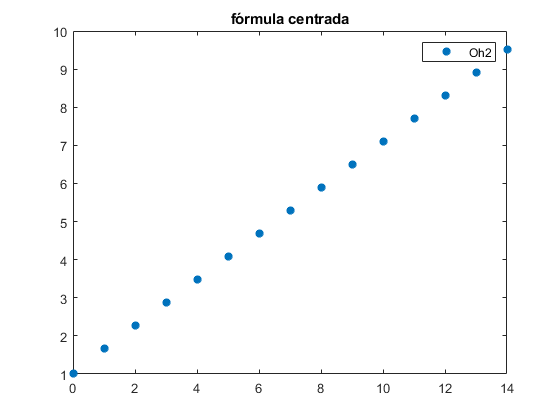

% Gràficament
plot(k,-log10(2*er2),'*','LineWidth',2), legend('Oh2'),title('fórmula centrada')

## Pràctica 17: Extrapolació de Richardson

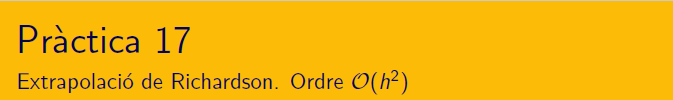

### **Ejercicio 7**

Se sabe que la derivada de $\ln(x)$ en $x=2$ tiene el valor de $f^{\prime}(2)=\frac 12$. Se pide:

a) Aproximar $f^{\prime}(2)$ mediante la fórmula $\mathbf{F2}\::f^{\prime}(x_0)\approx\frac{f(x_0+h)-f(x_0-h)}{2h},$ per $h_k=2^{-k}$ para $k=1,2,3\dots, 15.$

clearvars; format shortG
f = @(x)log(x);
a = 2; ve = 1/2; n = 15; hk = 1:n;
h = 1./2.^hk;
fp = (f(a+h)-f(a-h))./(2*h);
er = abs(fp-ve);
taula = [h(1:n);fp;er]';
varNames = {'1/2^k','f´(2)','error'};
T = array2table(taula,'VariableNames',varNames);disp(T)

      1/2^k        f´(2)       error   
    __________    _______    __________

           0.5    0.51083      0.010826
          0.25    0.50263     0.0026289
         0.125    0.50065    0.00065257
        0.0625    0.50016    0.00016286
       0.03125    0.50004    4.0696e-05
      0.015625    0.50001    1.0173e-05
     0.0078125        0.5    2.5432e-06
     0.0039063        0.5    6.3578e-07
     0.0019531        0.5    1.5895e-07
    0.00097656        0.5    3.9736e-08
    0.00048828        0.5    9.9341e-09
    0.00024414        0.5    2.4836e-09
    0.00012207        0.5    6.2073e-10
    6.1035e-05        0.5    1.5552e-10
    3.0518e-05        0.5    3.8199e-11



b) Usad la técnica de Extrapolación de Richardson para obtener $f^{\prime}(2)$ con más decimales correctos. Calculad el error absolut opara cada una de las aproximaciones obtenidas. Presentar los resultados en una tabla T3. Representad el error en una gráfica, absicisas $k=1,2,3\dots, 15$ y ordenadas $log_{10}(error)$.

**Primera columna N_1**

disp(T)

      1/2^k        f´(2)       error   
    __________    _______    __________

           0.5    0.51083      0.010826
          0.25    0.50263     0.0026289
         0.125    0.50065    0.00065257
        0.0625    0.50016    0.00016286
       0.03125    0.50004    4.0696e-05
      0.015625    0.50001    1.0173e-05
     0.0078125        0.5    2.5432e-06
     0.0039063        0.5    6.3578e-07
     0.0019531        0.5    1.5895e-07
    0.00097656        0.5    3.9736e-08
    0.00048828        0.5    9.9341e-09
    0.00024414        0.5    2.4836e-09
    0.00012207        0.5    6.2073e-10
    6.1035e-05        0.5    1.5552e-10
    3.0518e-05        0.5    3.8199e-11



**Primera extrapolació, columna N_2**

T1(1) = 0;
T1(2:n) = (4*fp(2:n)-fp(1:n-1))/3;
er2 = abs(T1-ve); er2(1) = 0;
taula1 = [h(1:n);fp;T1;er2]';
varNames = {'1/2^k','N_1 = f´(2)','N_2 = f´(2)','error'};
T = array2table(taula1,'VariableNames',varNames); disp(T)

      1/2^k       N_1 = f´(2)    N_2 = f´(2)      error   
    __________    ___________    ___________    __________

           0.5      0.51083              0               0
          0.25      0.50263         0.4999       0.0001034
         0.125      0.50065        0.49999      6.1898e-06
        0.0625      0.50016            0.5       3.828e-07
       0.03125      0.50004            0.5      2.3863e-08
      0.015625      0.50001            0.5      1.4904e-09
     0.0078125          0.5            0.5      9.3139e-11
     0.0039063          0.5            0.5      5.8217e-12
     0.0019531          0.5            0.5      3.8369e-13
    0.00097656          0.5            0.5               0
    0.00048828          0.5            0.5      5.6843e-14
    0.00024414          0.5            0.5      1.1369e-13
    0.00012207          0.5          

**Segona extrapolació, columna N_3**

T2(1:2) = 0;
T2(3:n) = (4^2*T1(3:n)-T1(2:n-1))/(4^2-1);
er3 = abs(T2-ve); er3(1:2) = 0;
taula2 = [h(1:n);fp;T1;T2;er3]';
varNames = {'1/2^k','N_1 = f´(2)','N_2 = f´(2)','N_3 = f´(2)','error'};
T = array2table(taula2,'VariableNames',varNames); disp(T)

      1/2^k       N_1 = f´(2)    N_2 = f´(2)    N_3 = f´(2)      error   
    __________    ___________    ___________    ___________    __________

           0.5      0.51083              0            0                 0
          0.25      0.50263         0.4999            0                 0
         0.125      0.50065        0.49999          0.5        2.9086e-07
        0.0625      0.50016            0.5          0.5        4.3263e-09
       0.03125      0.50004            0.5          0.5         6.679e-11
      0.015625      0.50001            0.5          0.5        1.0411e-12
     0.0078125          0.5            0.5          0.5        1.4322e-14
     0.0039063          0.5            0.5          0.5        6.1062e-16
     0.0019531          0.5            0.5          0.5         2.115e-14
    0.00097656 

**Tercera extrapolació, columna N_4**

T3(1:3) = 0;
T3(4:n) = (4^3*T2(4:n)-T2(3:n-1))/(4^3-1);
er4 = abs(T3-ve); er4(1:3) = 0;
taula3 = [h(1:n);fp;T1;T2;T3;er4]';
varNames = {'1/2^k','N_1 = f´(2)','N_2 = f´(2)','N_3 = f´(2)','N_4 = f´(2)','error'};
T = array2table(taula3,'VariableNames',varNames); disp(T)

      1/2^k       N_1 = f´(2)    N_2 = f´(2)    N_3 = f´(2)    N_4 = f´(2)      error   
    __________    ___________    ___________    ___________    ___________    __________

           0.5      0.51083              0            0              0                 0
          0.25      0.50263         0.4999            0              0                 0
         0.125      0.50065        0.49999          0.5              0                 0
        0.0625      0.50016            0.5          0.5            0.5        2.2186e-10
       0.03125      0.50004            0.5          0.5            0.5        8.2162e-13
      0.015625      0.50001            0.5          0.5            0.5         2.609e-15
     0.0078125          0.5            0.5          0.5            0.5        1.998

c) Respresentad las cifras decimales correctas en una gráfica con $k=1,2,3\dots, 15$ en el eje de abscisas.

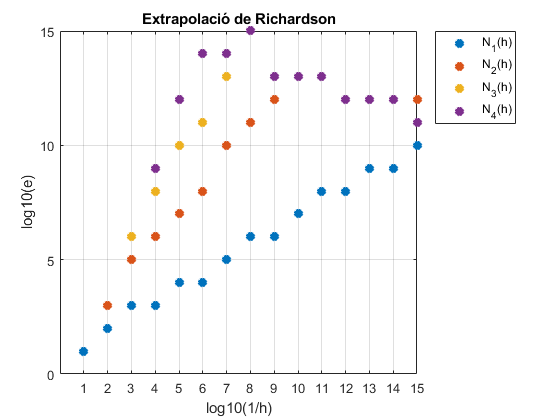

%% Gràfic
figure(1)
plot(hk,-fix(log10(er)),'*',hk,-fix(log10(er2)),'*',hk,-fix(log10(er3)),'*',hk,-fix(log10(er4)),'*','LineWidth',4);grid;
xlabel('log10(1/h)'); ylabel('log10(e)'); title('Extrapolació de Richardson')
legend('N_1(h)','N_2(h)','N_3(h)','N_4(h)','Location','bestoutside'),xticks([1:n])

### Ejercicio 8

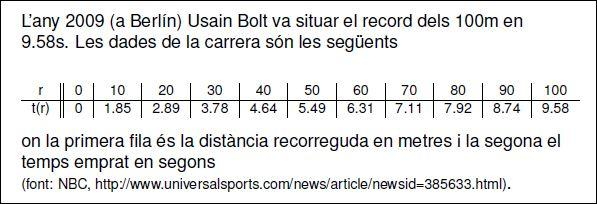

Calculeu una aproximació de la velocitat i l'acceleració en la carrera. Feu una representació gràfica 

dels valors obtinguts

format short g
r = 0:10:100;
t = [0 1.85 2.89 3.78 4.64 5.49 6.31 7.11 7.92 8.74 9.58];
disp([r;t]')

            0            0
           10         1.85
           20         2.89
           30         3.78
           40         4.64
           50         5.49
           60         6.31
           70         7.11
           80         7.92
           90         8.74
          100         9.58



**Velocitat i acceleració**

k = length(r);
v(1:k) = 0; a(1:k) = 0;
for i = 2:k
    v(i) = (r(i)-r(i-1))/(t(i)-t(i-1));
    a(i) = (v(i)-v(i-1))/(t(i)-t(i-1));
end
taula = [r;t;v;a]'

taula =             0            0            0            0
           10         1.85       5.4054       2.9218
           20         2.89       9.6154       4.0481
           30         3.78       11.236       1.8209
           40         4.64       11.628      0.45576
           50         5.49       11.765      0.16094
           60         6.31       12.195       0.5249
           70         7.11         12.5       0.3811
           80         7.92       12.346     -0.19052
           90         8.74       12.195     -0.18361


**Gràfics**

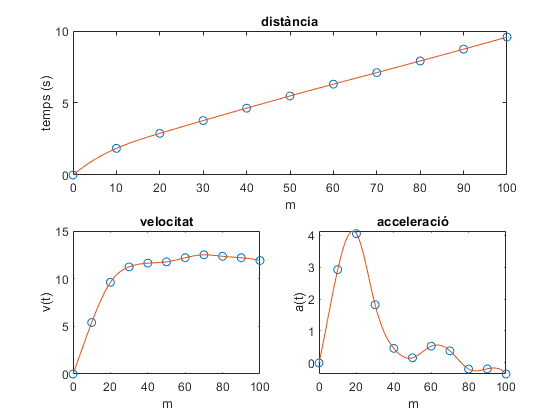

xx = 0:1:100;
rr = spline(r,t,xx);
subplot(2,2,[1,2]),plot(r,t,'o',xx,rr)
xlabel('m'); ylabel('temps (s)');
title('distància')
vv = spline(r,v,xx);
subplot(2,2,3),plot(r,v,'o',xx,vv)
xlabel('m'); ylabel('v(t)');
title('velocitat'),xticks([0,20,40,60,80,100])
aa = spline(r,a,xx);
subplot(2,2,4),plot(r,a,'o',xx,aa);
xlabel('m'); ylabel('a(t)');
title('acceleració'),xticks([0,20,40,60,80,100])

`Document preparat per Mª Àngela Grau Gotés (prof. responsable CN)`